clear;

stepend = 500;   %シミュレーションステップ数
steps = 1:stepend;

% 状態変数、推定状態変数、観測値の定義
x = zeros(2,stepend);
x(:,1) = [0;0.1]; % 状態変数の初期値をセット
hatx = zeros(2,stepend);
hatx(:,1) = [0;0]; % 推定状態変数の初期値をセット
y = zeros(1,stepend);

% 誤差の分散共分散行列(1ステップ分)の定義
% P_k = [0 0; 0 0];
P_k = [0.017901295622529 0.048176623416079;
    0.048176623416079 0.171576386080935];
% 誤差の分散共分散行列(各ステップ毎の値を保持する)の定義
P = zeros(2,2,stepend);
P(:,:,1) = P_k; % Pの初期値をセット
P_ = zeros(2,2,stepend); % 事前誤差共分散行列(事後と共通の変数にもできる)
P_(:,:,1) = P_k; % Pの初期値をセット

% プロセスノイズv、観測ノイズwの定義
sigmav = 0.1;
sigmaw = 0.5;
Q = sigmav*sigmav;
R = sigmaw*sigmaw;

Ts = 0.01;
A = [1 Ts; 0 1];
b = [0.2;1];
c = [1;0];
rng(5,"twister");

% (2)オフライン計算で求めた分散共分散行列とkalmanで求めたものが一致する点の検証
% シミュレーションには使わない。結果の比較にのみ使う。
sys = ss(A,[[0;0] b],c',[0 0],Ts);
[syskalmf,L_kalmf,P_kalmf,Mx,Z_kalmf,My] = kalman(sys,Q,R,0);

% 時変カルマンゲインの定義
K = zeros(2,stepend);

% 推定誤差を保存する配列
e_stored = zeros(2,stepend);
P_act_stored = zeros(2,2,stepend);
score = 0;
sigmaP = zeros(2,stepend);

% (1)オフライン計算でもゲインや分散共分散行列が変わらない点の検証
% 事前に、時変ゲインと誤差共分散行列だけを求める。
P_bef = zeros(2,2,stepend);
K_bef = zeros(2,stepend);
for k =2:stepend
    P_bef(:,:,k) = A*P_bef(:,:,k-1)*A' + b*Q*b';
    K_bef(:,k) = P_bef(:,:,k)*c/(c'*P_bef(:,:,k)*c+R);
    P_bef(:,:,k) = (eye(2)-K_bef(:,k)*c')*P_bef(:,:,k)*(eye(2)-K_bef(:,k)*c')' + K_bef(:,k)*R*K_bef(:,k)';
end

% (3)定常カルマンフィルタを用いても、ある程度時間が経ったときの動きはまったく同じ点
% 定常カルマンフィルタを使った場合の状態変数、時変カルマンゲインの定義
hatx_fix = zeros(2,stepend);
hatx_fix(:,1) = [0;0];
K_fix = K_bef(:,end);

% シミュレーションループ
for k =2:stepend
    % 観測対象からのサンプリング
    x(:,k) = A * x(:,k-1) + b*randn*sigmav;
    x_k = x(:,k);
    y(k) = c'*x_k + randn*sigmaw;

    % (3)定常カルマンフィルタを用いても、ある程度時間が経った後の動きは同じ点の検証
    hatx_fix(:,k) = A * hatx_fix(:,k-1) + K_fix * (y(k)-c'*A*hatx_fix(:,k-1));

    % 予測ステップ
    hatx_ = A * hatx(:,k-1);

    % 事前誤差共分散行列の更新
    P_(:,:,k) = A*P(:,:,k-1)*A' + b*Q*b';
    P_k = P_(:,:,k);

    % カルマンゲインの算出
    K(:,k) = P_k*c/(c'*P_k*c+R);
    K_k = K(:,k);

    % 更新ステップ
    hatx(:,k) = hatx_ + K_k * (y(k)-c'*hatx_);

    % 事後誤差共分散行列の更新
    P(:,:,k) = (eye(2)-K_k*c')*P_k*(eye(2)-K_k*c')' + K_k*R*K_k';

    e_k = x(:,k) - hatx(:,k);
    P_act_stored(:,:,k) = e_k * e_k';
    score = score + trace(P_act_stored(:,:,k));

    sigmaP(:,k)=sqrt(diag(P(:,:,k)));
end

推定結果のプロット

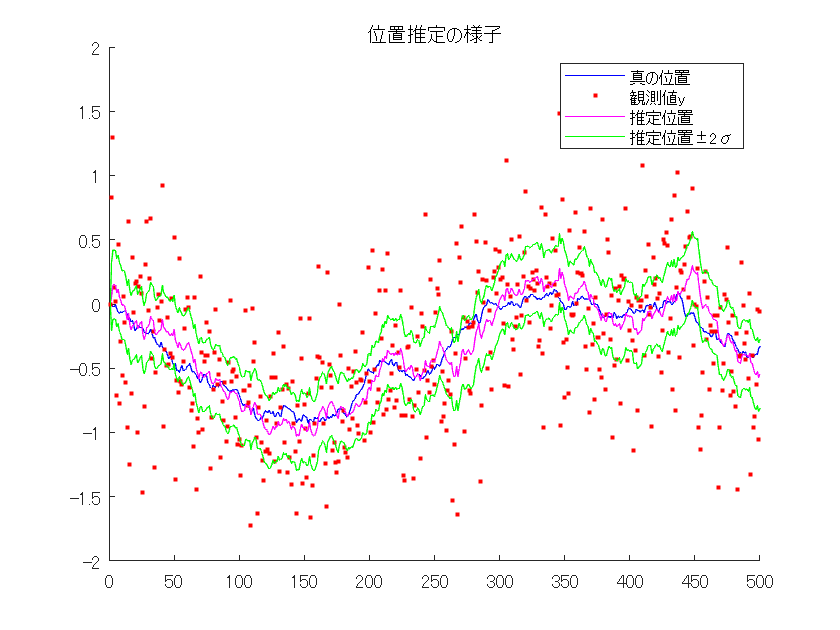

figure; hold on;
plot(x(1,:),'-b');
plot(y,'.r');
plot(hatx(1,:),'-m');
plot(hatx(1,:)+2*sigmaP(1,:),'-g');
plot(hatx(1,:)-2*sigmaP(1,:),'-g');
legend({'真の位置','観測値y','推定位置','推定位置±2σ'})
title('位置推定の様子')
ylim([-2 2]);

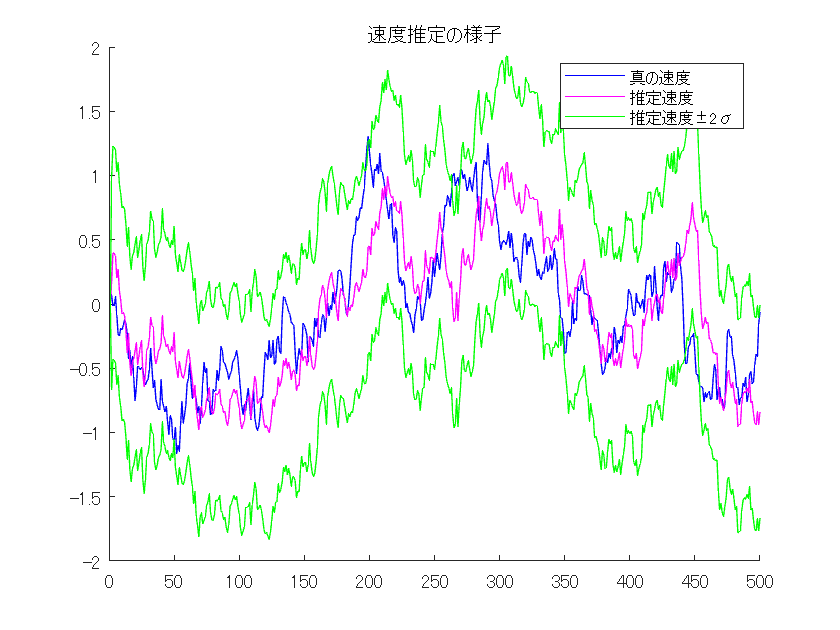


figure; hold on;
plot(x(2,:),'-b');
plot(hatx(2,:),'-m');
plot(hatx(2,:)+2*sigmaP(2,:),'-g');
plot(hatx(2,:)-2*sigmaP(2,:),'-g');
legend({'真の速度','推定速度','推定速度±2σ'})
title('速度推定の様子')
ylim([-2 2]);


lowerBound = hatx(1,:) - 2*sigmaP(1,:);
upperBound = hatx(1,:) + 2*sigmaP(1,:);
numOutside = sum( x(1,:) < lowerBound | x(1,:) > upperBound );
fprintf('推定位置が±2σから逸脱した割合:%.2f',(1-numOutside/stepend))

推定位置が±2σから逸脱した割合:0.97

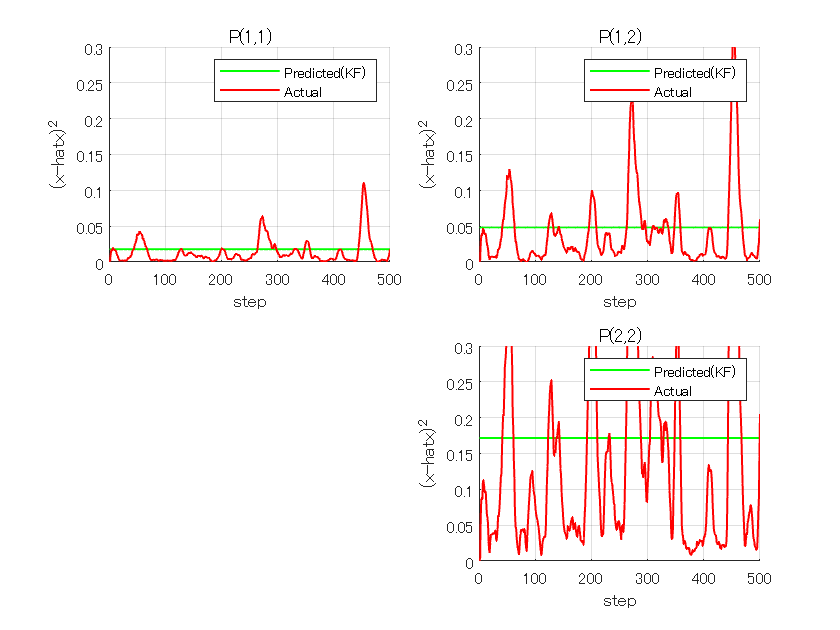



% シミュレーション内の誤差分散共分散行列Pの計算
% 簡易的に、移動平均によって求める。
window = 10; % 移動平均の点数
[rows, cols, ~] = size(P_act_stored);
P_act_movavg = zeros(rows, cols, stepend);

%% 分散共分散行列Pの要素のプロット

%-- プロットしたいPの要素と、それを表示するサブプロット番号を対応付け --
plotElems = [1 1; 1 2; 2 2];     % (2,1)は省略
subPositions = [1, 2, 4];       % subplot(2,2,1), (2,2,2), (2,2,4) を使う

for k = 1:stepend
    if k < window
        % 初期の k が window 未満の場合は、1 から k までの平均を計算
        P_act_movavg(:,:,k) = mean(P_act_stored(:,:,1:k), 3);
    else
        % k >= window のときは、直近 window 点の平均
        P_act_movavg(:,:,k) = mean(P_act_stored(:,:,(k-window+1):k), 3);
    end
end

figure;
for n = 1:size(plotElems,1)
    i1 = plotElems(n,1);
    i2 = plotElems(n,2);
    subplot(2,2, subPositions(n));
    hold on;grid on;

    %-- カルマンフィルタの推定P --
    plot(squeeze(P(i1,i2,:)), '-g', 'LineWidth',1);
    %-- 実測誤差から計算したP --
    plot(squeeze(P_act_movavg(i1,i2,:)), '-r', 'LineWidth',1);

    title(sprintf('P(%d,%d)', i1, i2));
    xlabel('step');
    ylabel('(x-hatx)^2');
    legend('Predicted(KF)','Actual','Location','northeast');
    ylim([0 0.3]);
end

%-- 余白にしたい (2,1)成分の箇所を subplot(2,2,3) で空ける場合 --
subplot(2,2,3);
axis off;
hold off;


% 誤差共分散行列P のトレースの累積値
fprintf('Pの対角要素の累積(スコア):%s',score)

Pの対角要素の累積(スコア):8.304494e+01

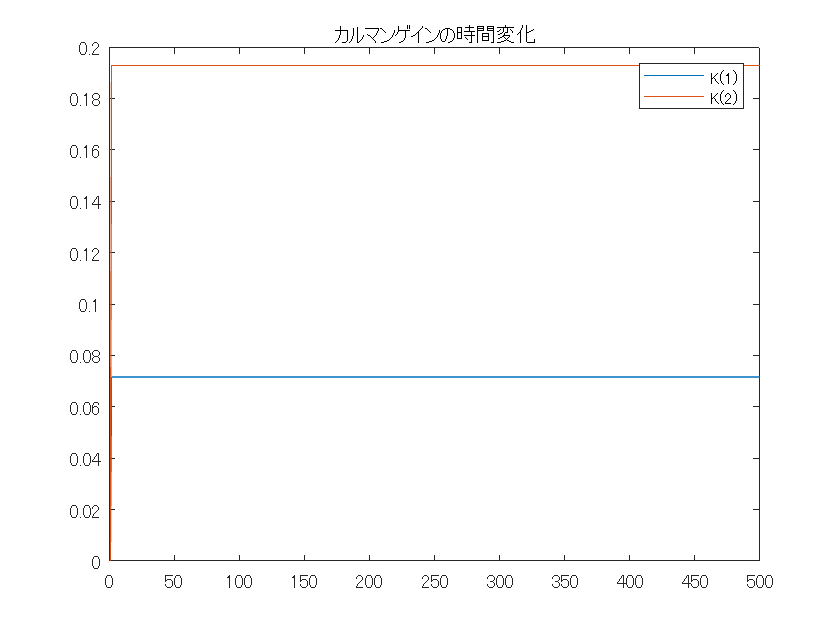


% (1)オフライン計算でもゲインや分散共分散行列が変わらない点の検証
% 演算場所が違うだけなので、計算結果は(浮動小数であることを加味しても)まったく同じになる
if (isequal(K_bef, K) && isequal(P_bef, P))
    fprintf('KとPの計算結果は、事前計算・シミュレーションループ内での計算どちらも一致。');
end

% ゲインの時系列の表示
figure;
plot(steps,K(1,:),steps,K(2,:))
legend({'K(1)','K(2)'});
title('カルマンゲインの時間変化')


% 推定誤差の平均がほぼゼロになることの確認
fprintf('位置推定誤差の平均:%s',mean(x(1,:)-hatx(1,:)))

位置推定誤差の平均:-1.312684e-02

fprintf('速度推定誤差の平均:%s',mean(x(2,:)-hatx(2,:)))

速度推定誤差の平均:-1.165373e-02

時変のカルマンフィルタと定常カルマンフィルタの比較

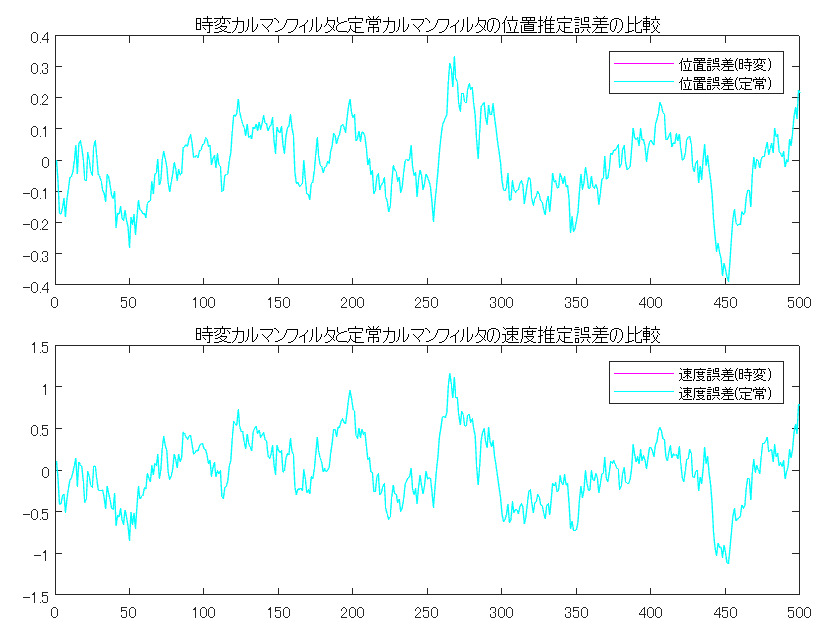

figure;
tiledlayout(2,1, 'TileSpacing','compact', 'Padding','compact');

% (3)定常カルマンフィルタを用いても、ある程度時間が経った後の動きは同じ点の検証
nexttile
plot(steps,x(1,:)-hatx(1,:),'-m',steps,x(1,:)-hatx_fix(1,:),'-c');
legend({'位置誤差(時変)','位置誤差(定常)'})
title('時変カルマンフィルタと定常カルマンフィルタの位置推定誤差の比較')

nexttile;
plot(steps,x(2,:)-hatx(2,:),'-m',steps,x(2,:)-hatx_fix(2,:),'-c');
legend({'速度誤差(時変)','速度誤差(定常)'})
title('時変カルマンフィルタと定常カルマンフィルタの速度推定誤差の比較')


% (2)オフライン計算で求めた分散共分散行列とkalmanで求めたものが一致する点の検証
% kalmanで求めた誤差共分散行列と、シミュレーション内の定常値はほぼ一致する
fprintf('kalman関数でのPとシミュレーション結果のP(の定常値)の差:%s',trace(Z_kalmf-P(:,:,end)))

kalman関数でのPとシミュレーション結果のP(の定常値)の差:-2.810252e-15

`カルマンフィルタの位置推定・速度推定の伝達関数の特性を確認する`

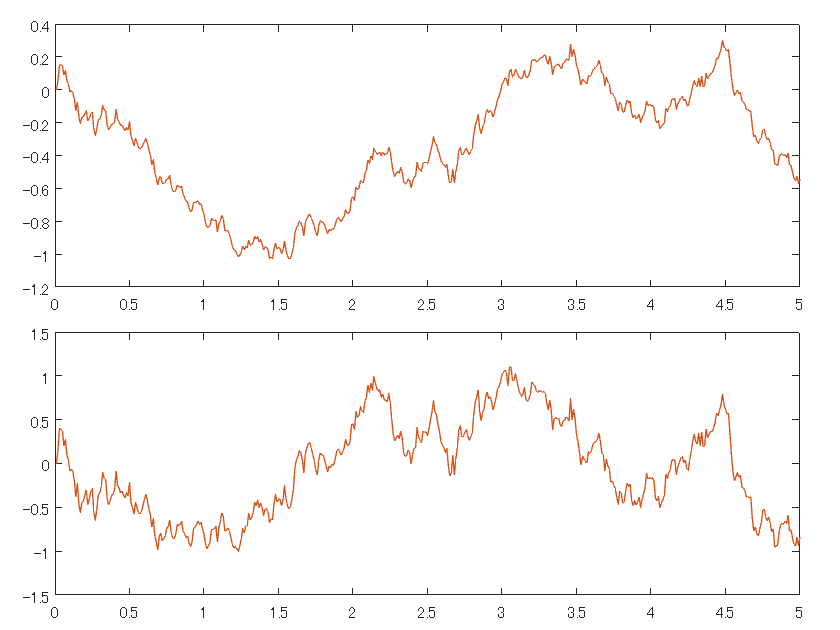

k1 = K(1,end);
k2 = K(2,end);
z = tf('z',Ts);
hatp_flt = (k1*(z-1)+k2*Ts) * z / ((z-1)^2 + (k1+k2*Ts)*(z-1) + k2*Ts);
hatq_flt = k2*(z-1)* z / ((z-1)^2 + (k1+k2*Ts)*(z-1) + k2*Ts);

[psim,tsim] = lsim(hatp_flt,y,steps*Ts);
[qsim,~] = lsim(hatq_flt,y,steps*Ts);

% 伝達関数に対する応答としても一致する
figure;
tiledlayout(2,1, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot(tsim,psim,tsim,hatx_fix(1,:))
nexttile;
plot(tsim,qsim,tsim,hatx_fix(2,:))

max(psim-hatx_fix(1,:)')

ans = 9.4369e-15

max(qsim-hatx_fix(2,:)')

ans = 1.2657e-14

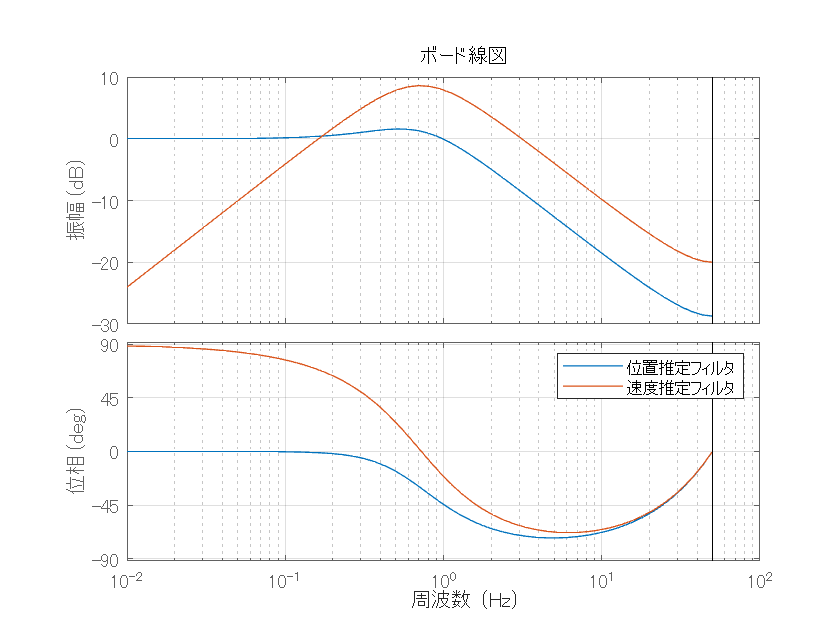


figure;
bode(hatp_flt,hatq_flt)
grid on;
legend({'位置推定フィルタ','速度推定フィルタ'})